## Lab 2.) Part B

The function ECEN380L2H is available on Canvas (Ilearn). The function prototype is as follows: 

                                function [ny, y] = E380L2H(nx, x, H) 

where, 

                Variable name                        Description 

                x                                             Input signal vector 

                y                                             Output signal vector 

                nx                                           Input time vector 

                ny                                           Output time vector 

                H                                            System selector (1, 2, 3) 

Come up with different x and nx vectors to test with each of the three systems (H = 1, H = 2, and H = 3). Based on the output of the function, determine whether the system could be **memoryless, causal, linear, **and **time invariant.** Show your input and output vectors, plots, and justify your answers. (Hint: This part is similar to problem 1.75 and 1.76). 

## Systems 1-3 Memoryless/ Causal Tests

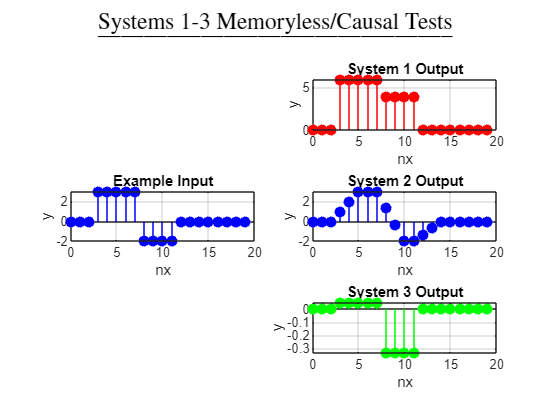

clf; % Clear current figure (so can run multiple subplots at once)
nx = 0:19; 
x_original = zeros(size(nx));    
x_original(nx >= 3 & nx <= 7) = 3;  
x_original(nx >= 8 & nx <= 11) = -2;  

subplot(3, 2, 3);   
stem(nx, x_original,'filled','Color','b') 
title('Example Input'); % Memoryless/Causal Test
xlabel('nx');
ylabel('y');
grid on;

y = E380L2H(nx, x_original, 1); % System 1

subplot(3, 2, 2);   % # rows, # columns, index
stem(nx, y(1:20),'filled','Color','r') 
title('System 1 Output'); % Memoryless/Causal Test
xlabel('nx');
ylabel('y');
grid on;

y = E380L2H(nx, x_original, 2); % System 2

subplot(3, 2, 4);   
stem(nx, y(1:20),'filled','Color','b') 
title('System 2 Output'); % Memoryless/Causal Test
xlabel('nx');
ylabel('y');
grid on;


y = E380L2H(nx, x_original, 3); % System 3

subplot(3, 2, 6);   
stem(nx, y(1:20),'filled','Color','g') 
title('System 3 Output'); % Memoryless/Causal Test
xlabel('nx');
ylabel('y');
grid on;
sgtitle('\underline{Systems 1-3 Memoryless/Causal Tests}', 'Interpreter', 'latex'); % Overall Title

## System 1 Linearity Test

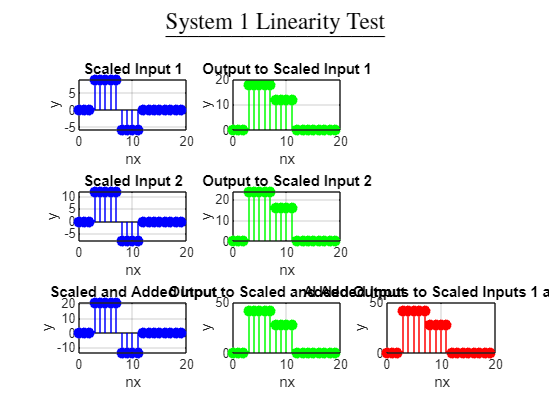

clf; % Clear current figure (so can run multiple subplots at once)
nx = 0:19; 
x_original = zeros(size(nx));    
x_original(nx >= 3 & nx <= 7) = 3;  
x_original(nx >= 8 & nx <= 11) = -2;  

a = 3;
b = 4;
linear_test_x1 = a * x_original;
linear_test_x2 = b * x_original;
linear_test_x_combined = linear_test_x1 + linear_test_x2;

y_separate_1 = E380L2H(nx, linear_test_x1, 1); % System 1
y_separate_2 = E380L2H(nx, linear_test_x2, 1); % System 1
y_together = E380L2H(nx, linear_test_x_combined, 1); % System 1
y_separate_added = y_separate_1 + y_separate_2;

subplot(3, 3, 1);   
stem(nx, linear_test_x1(1:20),'filled','Color','b') 
title('Scaled Input 1'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 2);   
stem(nx, y_separate_1(1:20),'filled','Color','g') 
title('Output to Scaled Input 1'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 4);   
stem(nx, linear_test_x2(1:20),'filled','Color','b') 
title('Scaled Input 2'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 5);   
stem(nx, y_separate_2(1:20),'filled','Color','g') 
title('Output to Scaled Input 2'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 7);   
stem(nx, linear_test_x_combined(1:20),'filled','Color','b') 
title('Scaled and Added Input'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 8);   
stem(nx, y_together(1:20),'filled','Color','g') 
title('Output to Scaled and Added Input'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 9);   
stem(nx, y_separate_added(1:20),'filled','Color','r') 
title('Added Outputs to Scaled Inputs 1 and 2'); 
xlabel('nx');
ylabel('y');
grid on;
sgtitle('\underline{System 1 Linearity Test}', 'Interpreter', 'latex'); 

## System 2 Linearity Test

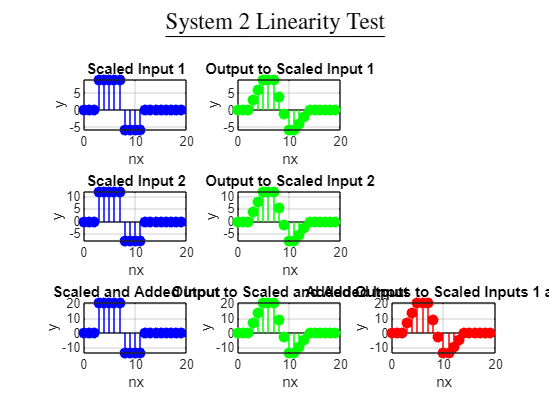


clf; % Clear current figure (so can run multiple subplots at once)
nx = 0:19; 
x_original = zeros(size(nx));    
x_original(nx >= 3 & nx <= 7) = 3;  
x_original(nx >= 8 & nx <= 11) = -2;  

a = 3;
b = 4;
linear_test_x1 = a * x_original;
linear_test_x2 = b * x_original;
linear_test_x_combined = linear_test_x1 + linear_test_x2;

y_separate_1 = E380L2H(nx, linear_test_x1, 2); % System 2
y_separate_2 = E380L2H(nx, linear_test_x2, 2); % System 2
y_together = E380L2H(nx, linear_test_x_combined, 2); % System 2
y_separate_added = y_separate_1 + y_separate_2;

subplot(3, 3, 1);   
stem(nx, linear_test_x1(1:20),'filled','Color','b') 
title('Scaled Input 1'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 2);   
stem(nx, y_separate_1(1:20),'filled','Color','g') 
title('Output to Scaled Input 1'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 4);   
stem(nx, linear_test_x2(1:20),'filled','Color','b') 
title('Scaled Input 2'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 5);   
stem(nx, y_separate_2(1:20),'filled','Color','g') 
title('Output to Scaled Input 2'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 7);   
stem(nx, linear_test_x_combined(1:20),'filled','Color','b') 
title('Scaled and Added Input'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 8);   
stem(nx, y_together(1:20),'filled','Color','g') 
title('Output to Scaled and Added Input'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 9);   
stem(nx, y_separate_added(1:20),'filled','Color','r') 
title('Added Outputs to Scaled Inputs 1 and 2'); 
xlabel('nx');
ylabel('y');
grid on;
sgtitle('\underline{System 2 Linearity Test}', 'Interpreter', 'latex'); 

## System 3 Linearity Test

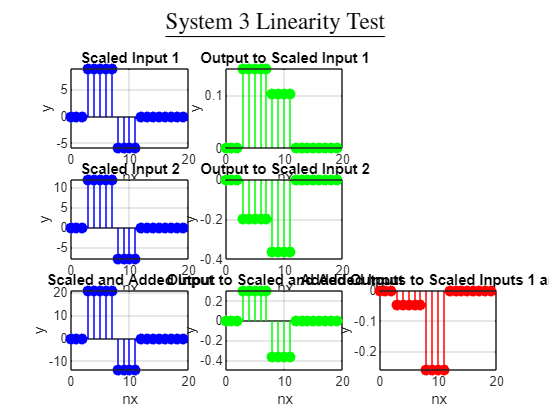


clf; % Clear current figure (so can run multiple subplots at once)
nx = 0:19; 
x_original = zeros(size(nx));    
x_original(nx >= 3 & nx <= 7) = 3;  
x_original(nx >= 8 & nx <= 11) = -2;  

a = 3;
b = 4;
linear_test_x1 = a * x_original;
linear_test_x2 = b * x_original;
linear_test_x_combined = linear_test_x1 + linear_test_x2;

y_separate_1 = E380L2H(nx, linear_test_x1, 3); % System 3
y_separate_2 = E380L2H(nx, linear_test_x2, 3); % System 3
y_together = E380L2H(nx, linear_test_x_combined, 3); % System 3
y_separate_added = y_separate_1 + y_separate_2;

subplot(3, 3, 1);   
stem(nx, linear_test_x1(1:20),'filled','Color','b') 
title('Scaled Input 1'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 2);   
stem(nx, y_separate_1(1:20),'filled','Color','g') 
title('Output to Scaled Input 1'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 4);   
stem(nx, linear_test_x2(1:20),'filled','Color','b') 
title('Scaled Input 2'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 5);   
stem(nx, y_separate_2(1:20),'filled','Color','g') 
title('Output to Scaled Input 2'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 7);   
stem(nx, linear_test_x_combined(1:20),'filled','Color','b') 
title('Scaled and Added Input'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 8);   
stem(nx, y_together(1:20),'filled','Color','g') 
title('Output to Scaled and Added Input'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(3, 3, 9);   
stem(nx, y_separate_added(1:20),'filled','Color','r') 
title('Added Outputs to Scaled Inputs 1 and 2'); 
xlabel('nx');
ylabel('y');
grid on;
sgtitle('\underline{System 3 Linearity Test}', 'Interpreter', 'latex'); 

## System 1 Time Variance Test

- Shift the original output w/ no shifted input

- Shift the input -> get new output

- Compare outputs -> same = time invariant, diff = time variant

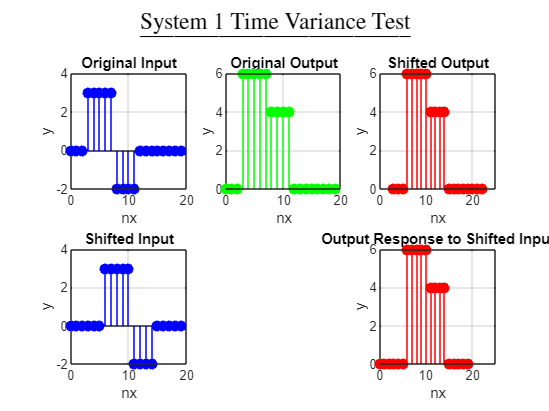

clf; % Clear current figure (so can run multiple subplots at once)
nx = 0:19; 
x_original = zeros(size(nx));    
x_original(nx >= 3 & nx <= 7) = 3;  
x_original(nx >= 8 & nx <= 11) = -2; 

x_shifted = zeros(size(nx));
x_shifted(nx >= 6 & nx <= 10) = 3;
x_shifted(nx >= 11 & nx <= 14) = -2;

y_reponse_to_shift = E380L2H(nx, x_shifted, 1); % System 1
% y_reponse_to_shift = E380L2H(nx + 3, x_original, 1); % System 1

y_original = E380L2H(nx, x_original, 1); % System 1

subplot(2, 3, 1);   
stem(nx, x_original(1:20),'filled','Color','b') 
title('Original Input'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 2);   
stem(nx, y_original(1:20),'filled','Color','g') 
title('Original Output'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 3);   
stem(nx+3, y_original(1:20),'filled','Color','r') 
xlim([0 25])
title('Shifted Output'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 4);   
stem(nx, x_shifted(1:20),'filled','Color','b') 
title('Shifted Input');
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 6);   
stem(nx, y_reponse_to_shift(1:20),'filled','Color','r') 
xlim([0 25])
title('Output Response to Shifted Input'); 
xlabel('nx');
ylabel('y');
grid on;
sgtitle('\underline{System 1 Time Variance Test}', 'Interpreter', 'latex'); 

## System 2 Time Variance Test

- Shift the original output w/ no shifted input

- Shift the input -> get new output

- Compare outputs -> same = time invariant, diff = time variant

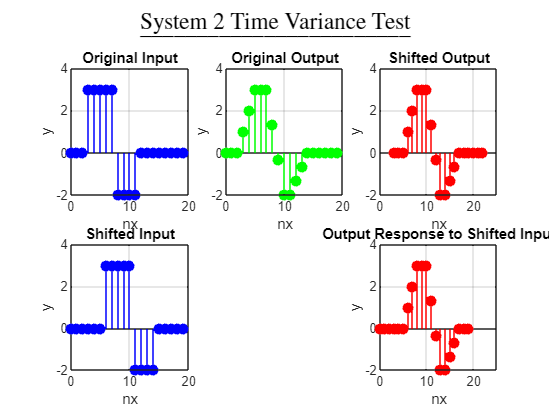

clf; % Clear current figure (so can run multiple subplots at once)
nx = 0:19; 
x_original = zeros(size(nx));    
x_original(nx >= 3 & nx <= 7) = 3;  
x_original(nx >= 8 & nx <= 11) = -2; 

x_shifted = zeros(size(nx));
x_shifted(nx >= 6 & nx <= 10) = 3;
x_shifted(nx >= 11 & nx <= 14) = -2;

y_reponse_to_shift = E380L2H(nx, x_shifted, 2); % System 2

y_original = E380L2H(nx, x_original, 2); % System 2

subplot(2, 3, 1);   
stem(nx, x_original(1:20),'filled','Color','b') 
title('Original Input'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 2);   
stem(nx, y_original(1:20),'filled','Color','g') 
title('Original Output'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 3);   
stem(nx+3, y_original(1:20),'filled','Color','r') 
xlim([0 25])
title('Shifted Output'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 4);   
stem(nx, x_shifted(1:20),'filled','Color','b') 
title('Shifted Input');
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 6);   
stem(nx, y_reponse_to_shift(1:20),'filled','Color','r') 
xlim([0 25])
title('Output Response to Shifted Input'); 
xlabel('nx');
ylabel('y');
grid on;
sgtitle('\underline{System 2 Time Variance Test}', 'Interpreter', 'latex'); 

## System 3 Time Variance Test

- Shift the original output w/ no shifted input

- Shift the input -> get new output

- Compare outputs -> same = time invariant, diff = time variant

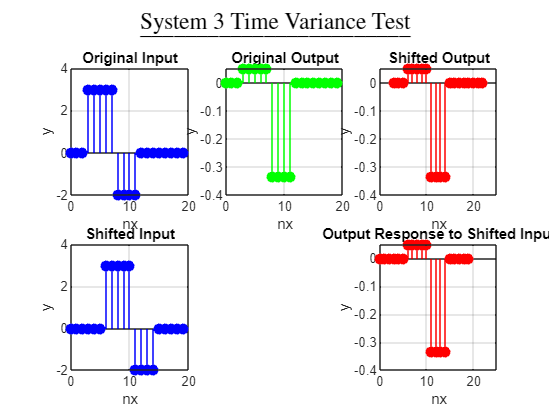

clf; % Clear current figure (so can run multiple subplots at once)
nx = 0:19; 
x_original = zeros(size(nx));    
x_original(nx >= 3 & nx <= 7) = 3;  
x_original(nx >= 8 & nx <= 11) = -2; 

x_shifted = zeros(size(nx));
x_shifted(nx >= 6 & nx <= 10) = 3;
x_shifted(nx >= 11 & nx <= 14) = -2;

y_reponse_to_shift = E380L2H(nx, x_shifted, 3); % System 3

y_original = E380L2H(nx, x_original, 3); % System 3

subplot(2, 3, 1);   
stem(nx, x_original(1:20),'filled','Color','b') 
title('Original Input'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 2);   
stem(nx, y_original(1:20),'filled','Color','g') 
title('Original Output'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 3);   
stem(nx+3, y_original(1:20),'filled','Color','r') 
xlim([0 25])
title('Shifted Output'); 
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 4);   
stem(nx, x_shifted(1:20),'filled','Color','b') 
title('Shifted Input');
xlabel('nx');
ylabel('y');
grid on;

subplot(2, 3, 6);   
stem(nx, y_reponse_to_shift(1:20),'filled','Color','r') 
xlim([0 25])
title('Output Response to Shifted Input'); 
xlabel('nx');
ylabel('y');
grid on;
sgtitle('\underline{System 3 Time Variance Test}', 'Interpreter', 'latex'); 